# UESTC3001: Dynamics and Control (2021-22)

# Lab1 - Transients in RLC Networks

## 1. Introduction

RLC networks are commonly used as bandpass and notch filters to selectively remove certain frequencies from the signal delivered to a load. They are used in oscillators and in circuits that are used in energy storage and power conversion such as pulse discharge circuits and voltage multipliers.  There are three different transient responses in RLC circuits – **overdamped**, **critically damped**, and **underdamped**.  Engineers select a type of damping when designing circuits to achieve a certain performance.  

For example, in the case of the pulse discharge circuit, such as some circuits used to send short, high voltage pulses to the lamp in a camera flash, a response is preferred that will causes all of the energy stored in the inductor or capacitor to be rapidly dissipated by the resistor in RLC network. The capacitor in a series RLC network and the inductor in the parallel RLC network will determine the amount of stored energy, which will, in turn, determine the brightness of the camera flash.  Thus, the objective in a pulse discharge circuit is to design an RLC network that releases most of the stored energy through the resistor within a specified amount of time, usually as short as possible. Thus, an engineer must consider both the natural frequency $\omega_o$ and the damping factor $\alpha$ when selecting components.

The transition between initial and final conditions for component voltages and currents is fastest in a critically damped circuit.  You can always design a critically damped circuit, but to have an RLC network that operate always at the point where$\omega_{o\;} =\alpha$, requires components that:

    (a) have extremely tight tolerances or are tunable (e.g., a trim potentiometer and variable capacitor) so that the magnitudes of the components can be tweaked to the required values, 

    (b) that have very little dependence on environmental variables such as ambient temperature and,

    (c) that behave as ideal component over the current, voltage, and frequency ranges of operation for the life of the circuit.  

As there are parasitic resistances, capacitances, and inductances in a number of components – even a resistor such as any of the ones from the Electronics Store should be modeled as an inductor in series with the parallel combination of a capacitor and the resistor to predict its operation over a reasonably wide range of frequencies.  Hence, an RLC network that operates as a critically damped circuit is difficult to achieve.

#### Lab Setup: RLC Network (*This lab exercise will be carried out in MATLAB. Please open the given file "Lab_1_workspace" using matlab for the remaining part of the lab)*

Given the circuit in Figure 1, where RLC are in series with R as the resistor, $L$, the inductor, $C$, the capacitor, $V$, the source voltage and, $I$, the current.

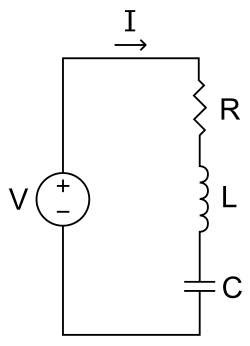

Figure 1: Simple series RLC network

- For example, to see the effect of varying damping factor$\zeta$ on the current $I$, if natural frequency $\omega_0 =1$rad/s, taking unity constants and using "plot_response", we can adjust the damping factor slider and observe the response when (a) Damping factor is less than 0, (b) Damping factor is 0, (c) Damping factor is 0.1, (d) Damping factor is 1, (e) Damping factor is greater than 1.

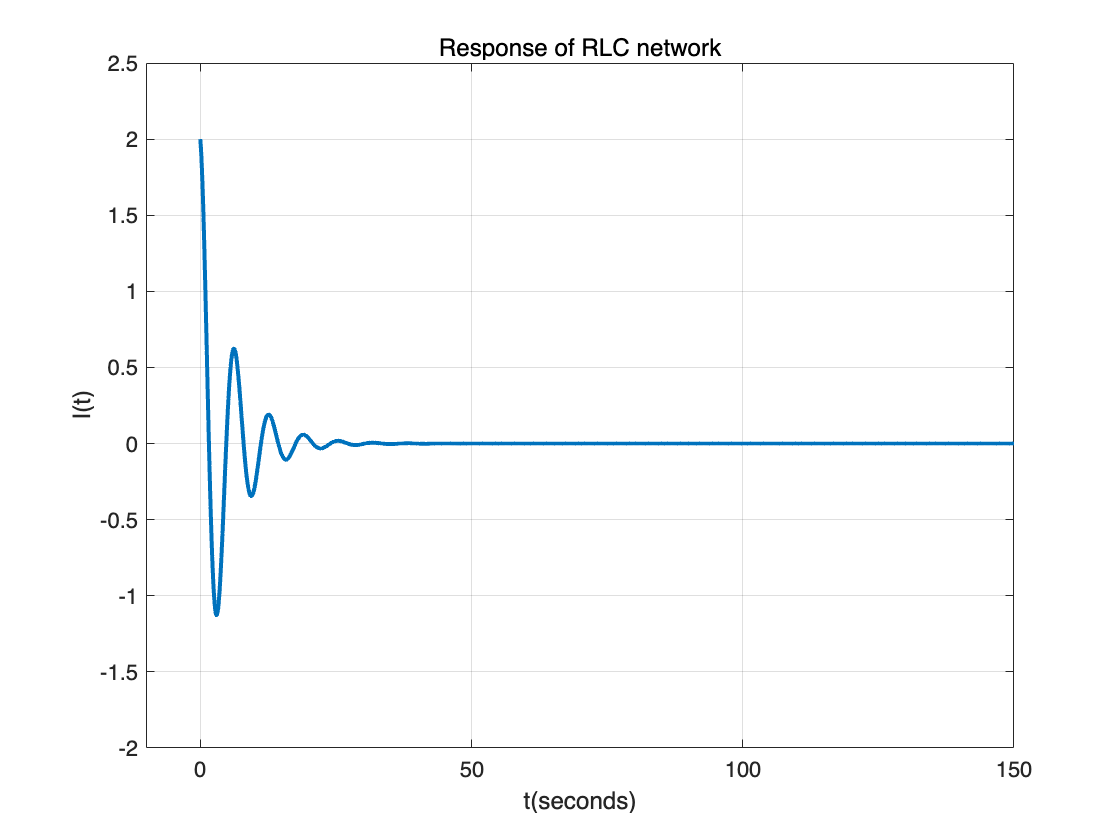

zeta = 0.185;
plot_response(zeta)

Study the output received at various damping factor values. Note that the response oscillates at Damping factor value close to zero, it is under-damped when the value is 0.1, it is critically damped at 1 and overdamped when the damping factor is greater than one.

Although essential in certain oscillator circuits, the underdamped response can be undesirable as it can take a long time for the signal to reach steady-state.  The signal in an underdamped RLC network will overshoot – the signal will temporarily change sign as the signal decays to zero in the case of a natural response or it can reach a much larger magnitude than the magnitude of the final steady-state signal in the case of a forced response.  The overshoot, which is also known as ringing, oscillates at the damped frequency of the RLC network $\omega_{d\;} =\sqrt{\omega_o^{2\;} -\alpha^2 }\;$and the rate of the exponential decay of the oscillations is determined by the damping factor. 

The magnitude of the overshoot must be taken into consideration when determining the maximum voltage and current specifications for the components selected for use in the circuit.  In addition to stressing components electrically, the overshoot of an underdamped circuit can also stress components mechanically because of rapid thermal expansion caused by a spike in the component’s temperature as a result of the dissipated power.  The stress can damage components, enhancing their non-ideal properties, and can reduce the components’ useable lifetime.                                                      

In the next experiment, we will explore how the value of a affects the ringing that occurs in an underdamped series RLC network.  The circuit that will be analyzed is shown in Figure 2.   $\alpha \;$ will be altered by varying the value of R1.  Note that this circuit is a bit more complicated than a simple series RLC circuit.  First, there is a Thévenin equivalent resistor  $R_{\textrm{th}}$, which is in series with the voltage source  $V_1$.  This resistor is used to model the resistance of the arbitrary waveform generator, which is a non-ideal voltage source.   Next, there is a resistor $R_2$ that is in parallel with the RLC network.  This resistor is used to ensure that the energy stored in the capacitor does not discharge directly into the arbitrary waveform generator, which could cause the current to flow into the voltage source.  Depending on the voltage source used, this may cause the voltage source to turn off and could possibly **damage** the arbitrary waveform generator.  Instead, the transient current generated while the capacitor discharges will be added to a dc current $\frac{V_1 }{R_{\textrm{th}} +R_2 }$ .   

The values that will be used in this experiment for  $V_1$, the inductor, the capacitor, and the resistors have been selected to insure that the arbitrary function generator will always act as a power generating element in the circuit.  Lastly, a lumped component model for a non-ideal inductor is used – a series combination of an ideal inductor  $L_1 \;$and a resistor $R_{\textrm{parasite}}$ , which is the resistance of the wire used to create the inductor.

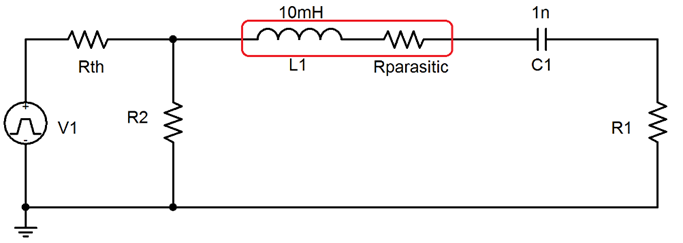

Figure 2: RLC circuit with series and non-series components for experiment

NOTE:  Caution should be used when designing a RLC network to ensure that the voltage and current specifications for the voltage source are not exceeded or it may be damaged.

## 2. Analysis (Lab 1 Q2)

**Lab 1 Q2A. Write the transfer function in time domain for the voltage across  **$C_1$** versus the input voltage **$V_1$ 

**Steps:**

- Convert $V_{1\;}$and $R_{\textrm{th}}$into its equivalent current source $I_x$ and parallel resistor

- Combine the parallel resistor with $R_2$ giving $R_{\textrm{eq}}$

- Convert $I_x$ and $R_{\textrm{eq}}$ into $V_x$ and $R_{\mathrm{eq2}}$

- Rearrange the components so as to get a **RLC** series circuit

- Apply mesh analysis to the **RLC** series

- Give the transfer function of $V_{\textrm{c1}} \;$as a function of $V_1$ and the component values.

Hint 1: Use Insert > Equation to type in equations and variables

Hint 2: A Norton equivalent circuit is related to the Thevenin equivalent by the following equations:

                      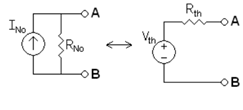 

Hint 3:  $V_L \left(t\right)=L\;\frac{d}{\textrm{dt}\;}i\left(t\right)$ and $i\left(t\right)=C\;\frac{d}{\textrm{dt}\;}V_c \left(t\right)$

**Type response here:**

%--------------------------------------

%--------------------------------------

**Lab 1 Q2B.** **Determine the natural frequency, attenuation, damping factor, and damping frequency of the circuit shown in Figure 2 where **$R_{\textrm{th}\;} =50\;\Omega$**, **$R_2 =47\;\Omega$**, **$R_{\textrm{parasitic}} =100\;\Omega$**, and a) **$R_{1\;} =300\;\Omega$** and b) **$R_{1\;} =3\;k\Omega$**.  Note that you should combine **$R_{\textrm{th}\;}$**, **$R_{\textrm{parasitic}}$**, **$R_1$**, and **$R_{2\;}$**into one equivalent resistor before performing these calculations**. Be careful with units!!! (Hz and rad/s are not the same)

Hint 4: 

    The natural angular frequency:  $\omega_o =\frac{1}{\sqrt{\textrm{LC}}}$

    the neper frequency or attenuation:  $\alpha =\frac{R}{2L}$ 

    The damping factor:  $\xi =\frac{\alpha }{\omega_o }$

    The damping frequency:  $\omega_d =\sqrt{\left(\omega_o^{2\;} -\alpha^2 \right)}=\omega_o \sqrt{1-\xi^2 \;}\;$

    Frequency:  $f=\frac{\omega }{2\pi \;}$ 

**Type response here:**

%--------------------------------------

%--------------------------------------

**Lab 1 Q2C.** Complete program in "***system_characteristics****" *to solve question 2b and set the output as a vector of **four** variables in this order natural frequency $f_0$, attenuation $\alpha \;$, damping factor $\zeta$, and damping frequency $f_d$.

Hint: You can use disp function to print out the natural frequency, attenuation, damping factor, and damping frequency.

%--------------------------------------

for $R_1 =300\;\Omega$,

system_charateristics(50, 47, 100, 300);

the natural frequency is: 1.6709e-05 Hz
the attenuation is: 1672878.0069
the damping factor is: 4.4486
the damping frequency is: 0-3.8546e-06i Hz


for $R_1 =3\;K\Omega$,

system_charateristics(50, 47, 100, 3000);

the natural frequency is: 1.947e-05 Hz
the attenuation is: 172878.0069
the damping factor is: 0.53571
the damping frequency is: 2.3058e-05 Hz


Hint: Use ***help system_characteristics ***at the command window to see the required inputs to the system_characteristics function

Check if this is the same as the answer you computed in 2b.

%--------------------------------------

**Lab 1 Q2D**. **For the two cases a) **$R_{1\;} =300\;\Omega$** and b) **$R_{1\;} =3\;k\Omega$**, determine the values for A1 and A2 in the equation for a forced response, **$v_c \left(t\right)=\left\lbrack A_1 \cos \left(\omega_d t\right)+A_2 \sin \left(\omega_d t\right)\right\rbrack e^{-\alpha t\;} +V_s$** when **$V_1 =2V\left\lbrack 1+2u\left(t\right)\right\rbrack$**, where is a unit step function.  Note that **$V_{s\;} \not= V_{1\;}$**. The solution will be the same as the case where **$V_1 =4\textrm{Vu}\left(t\right)$** because the transient response is only produced by the step function, not the d.c. component of **$V_1$.  

**Type response here:**

%--------------------------------------

%--------------------------------------

**Lab 1 Q2E. Complete program in "*****function_A******" *****to solve for A1 and A2 using the value of Vc(just before t=0) and Vc(at infinity).**

for $R_1 =300\;\Omega$, 

[~, alpha1, ~, w_d1] = system_charateristics(50, 47, 100, 300);

the natural frequency is: 0 Hz
the attenuation is: 0
the damping factor is: 0
the damping frequency is: 0 Hz


%given V1 = 2(1+2u(t));
R2 = 47; Rth = 50; %ohms
v1_before_0 = 2*(1+2*0);
v1_inf = 2*(1+2*1);
vc_before_0 = R2/(R2+Rth)*v1_before_0;
vc_inf = R2/(R2+Rth)*v1_inf;
[A11, A21] = function_A(alpha1, w_d1, vc_inf, vc_before_0);

the value of A1 is: 0
the value of A2 is: 0


for $R_1 =3000\;\Omega$,

[~, alpha2, ~, w_d2] = system_charateristics(50, 47, 100, 3000);

the natural frequency is: 0 Hz
the attenuation is: 0
the damping factor is: 0
the damping frequency is: 0 Hz


[A12, A22] = function_A(alpha2, w_d2, vc_inf, vc_before_0);

the value of A1 is: 0
the value of A2 is: 0


**Lab 1 Q2F.** **Complete the program "****plot_vc****" to plot the equations for the voltage across the capacitor developed in Step 3 on the same graph from t = 0 s to t = 0.25 ms**.

for $R_1 =300\;\Omega$,

plot_vc(A11, A21, alpha1, w_d1);

for $R_1 =3000\;\Omega$,

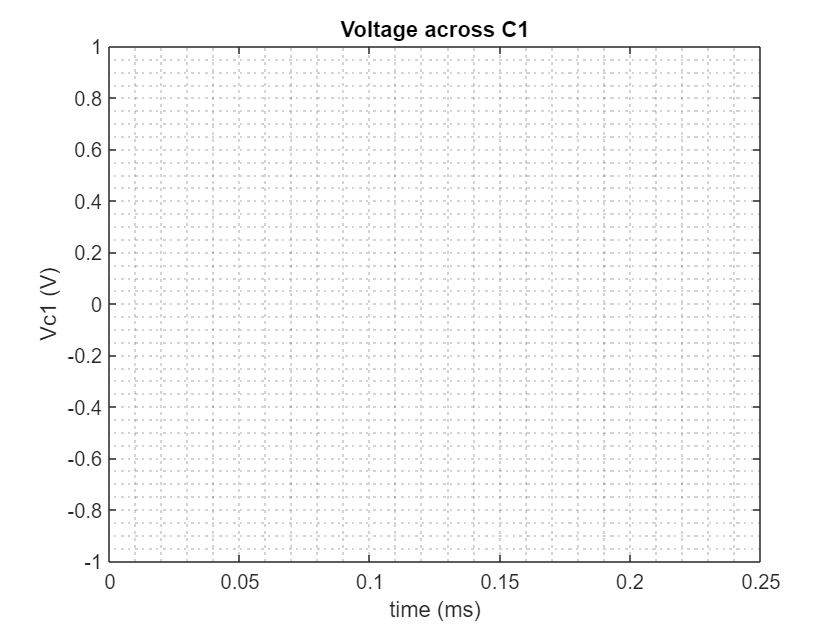

hold on; plot_vc(A12, A22, alpha2, w_d2);

If your graphs for (a) and (b) look like the plots below, congratulations! you have completed this task

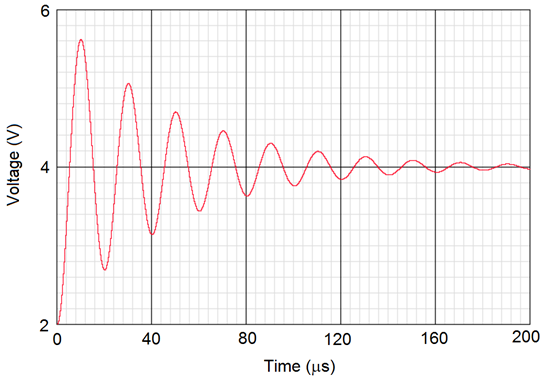    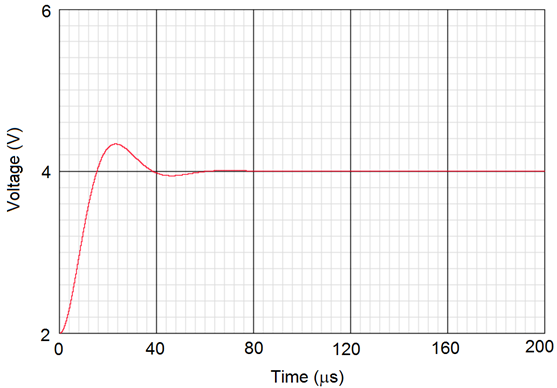

**Lab 1 Q2G. Using the codes you have already written, complete "****general_characteristics****" as a function of **$L_1$**, **$\alpha \;$**, and **$C_1$** which uses the sliders to show how each of the parameters **$L_1$**, **$\alpha \;$**, and **$C_1$** affect the oscillations in **$V_c$** in the circuit with **$R_1$**.**

L1      = 0.001;
C1      = 0;
alphar  = 20000;


general_charateristics(L1, C1, alphar, A11, A21);

## 3. Reflection (Lab 1 Q3)

**Using the "*****general_characteristics" *****function, given the three variables L, **$\alpha \;$**, and C, explain how each variable can reduce oscillations in voltage across **$C_{1\;}$** in the circuit with resistor **$R_{1\;}$**.**

- **A**. With reasons, state whether $\alpha \;$ increase or decrease?                                                                                                                        

- **B**. If $R_1$  is held constant, state with reasons whether the value of $L_1$ should increase or decrease to reduce the oscillations in the transient response?                                                                                                                                                            

- **C**. If $R_1$  is held constant, state with reasons whether the value of $C_1$ should increase or decrease to reduce the oscillations in the transient response?                                                                                                                                                             

- **D**. Given the relationships between energy, power, voltage, and resistance, do you expect that the energy stored in the capacitor will dissipate faster as $R_1$ increases?  Why or why not? 

- **E**. Given the relationship between energy, charge, voltage, and capacitance, would you expect that the amplitude of the voltage overshoot in the transient response to increase or decrease if the capacitance of $C_1$ is increased while the magnitudes of the other components in the circuit are held constant? 

## Include functions here:

1. Plot_response(zeta)

function plot_response(zeta)
%custom funtion to plot response of the graph
t=0:0.1:200;
omega = 1;
s1 = -1*omega*(zeta - sqrt(zeta^2-1)); %compute first variable s1
s2 = -1*omega*(zeta + sqrt(zeta^2-1)); %compute second variable s2
i= 1*exp(s1*t)+ 1*exp(s2*t); %compute current taking unity constants i.e. A1 = A2 = 1
plot(t,real(i),'linewidth',2); %plot command
xlabel('t(seconds)'), ylabel('I(t)'), title('Response of RLC network'),grid on; %titles and labels
if zeta<0 axis tight, else axis([-10 150 -2 2.5]);end %add flexible axis
end


2. System_characteristics($R_{\textrm{th}} ,R_2 ,\;$$R_{\textrm{ps}} ,$ $R_1$)

function [f_n, alpha, zeta, f_d] = system_charateristics(R_th, R_2, R_ps, R_1)
    %system_characteristics(R_th, R_2, R_ps, R_1)
    %function to compute system characteristics which include natural
    %frequency, f_n, attenuation, alpha, damping factor, zeta, and damping frequency, f_d
    %the function takes in R_th, R_2, R_ps and R_1, and outputs the system
    %characteristics in terms of the natural frequency, attenuation, the damping factor
    %and the damping frequency

    %% to be completed by student!!
    % write code here
    


    %% Comment out the next five lines below after you have completed your code
    f_n = 0; zeta = 0; alpha = 0; f_d=0; %comment out this line after completing your code
    Req=(R_th*R_2)/(R_th+R_2);
    R_2=R_1;
    Rs=Req+R_ps;
    L1=10e-3;
    C1=1e-9;
    omega_0=sqrt((Rs+R_2)/(L1*R_2*C1));
    f_n=(2*pi)/omega_0;
    alpha=0.5*(Rs/L1+1/(R_2*C1));
    zeta=(Rs/L1+1/(R_2*C1))/(2*sqrt((Rs+R_2)/(L1*R_2*C1)));
    omega_d=sqrt(omega_0^2-zeta^2*omega_0^2);
    f_d=(2*pi)/(omega_d);
    disp(['the natural frequency is: ', num2str(f_n), ' Hz']); %code to display output
    disp(['the attenuation is: ', num2str(alpha)]);
    disp(['the damping factor is: ', num2str(zeta)]);
    disp(['the damping frequency is: ', num2str(f_d), ' Hz']);

end


3. Function_a.m

function [A1, A2] = function_A(alfa, w_d, vc_inf, vc_before_0)
%functionA(alpha, w_f, vc_inf, vc_before_o)
% This function is to compute the values of A1 and A2, it takes in alpha,
% damping frequency, Vc at t=infinity and Vc just before t=0.


    %% to be completed by student!!
    % write code here
    


    %% Comment out the next four lines below after you have completed your code
A1 = 0;
A2 = 0;
disp(['the value of A1 is: ', num2str(A1)]); %code to display outputs
disp(['the value of A2 is: ', num2str(A2)]);

end


4. Plot_vc.m

function plot_vc(A1, A2, alpha, w_d)
%plot_vc(A1, A2, alpha, w_d) function takes in pre-computed values of A1,
%A2, attenuation alpha, and damping frequence w_d and gives out a sketch
%plot of the voltage across capacitor
%   Detailed explanation goes here
t = 0:1e-6:0.25e-3; %time range for plot
    %% to be completed by student!!
    % write code here
    


    %% Comment out the next one line below after you have completed your code
vc = 0;
grid minor;
plot(t*1e3,vc); %plot command
title('Voltage across C1') %title and labels
xlabel('time (ms)')
ylabel('Vc1 (V)')

axis tight
end

5. General_characteristics.m

function  general_charateristics(L_1, C_1, alpha, A1, A2)
    %general_charateristics(L_1, C_1, alpha, A1, A2)
    %function to compute general system characteristics
    %the function takes in the inductor value L_1, capacitor C_1, attenuation alpha, A1, A2 (computed earlier) 
    %plots the system characteristics

    %% to be completed by student!!
    % write code here    
    t = 0:1e-6:0.25e-3; %time range for plot
    
    
    

    %% Comment out the next one line below after you have completed your code
    vc = 0;
    figure %to use new plot window
    plot(t*1e3,vc); %plot command
    title('Voltage across C1') %title and labels
    xlabel('time (ms)')
    ylabel('Vc1 (V)')
    grid minor
    axis tight
end

**** You will be required to include answers (and programs) for Lab 1, Question 2G (Lab 1 Q2G) and Lab 1 Question 3 (Lab1 Q3) in their final report for assessment. The final report will be submitted at the end of Lab 4, but you are encouraged to answer the questions at the end of today's lab.**